clear;
x_a_values = [0. 5. 5.9 6. 7. 15.];
gd = 9.80665;
global fi_flag_Simulink

newline = sprintf('\n');

%% Trim aircraft to desired altitude and velocity

altitude = 15000; %input('Enter the altitude for the simulation (ft)  :  ');
velocity = 500; %input('Enter the velocity for the simulation (ft/s):  ');

FC_flag = 1; % Trim for steady wings-level flight
%% Initial guess for trim
%%
thrust = 5000;          % thrust, lbs
elevator = -0.09;       % elevator, degrees
alpha = 8.49;              % AOA, degrees
rudder = -0.01;             % rudder angle, degrees
aileron = 0.01;            % aileron, degrees

% Create a cell array to store line styles or colors
line_styles = {'-', '--', ':', '-.', '-', '--'};

figure(7);
hold on;
for i = 1:length(x_a_values)
    x_a = x_a_values(i);
    
    %% Find trim for lofi model at desired altitude and velocity
    disp(['Trimming Low Fidelity Model for x_a = ' num2str(x_a) ':']);
    fi_flag_Simulink = 0;
    [trim_state_lo, trim_thrust_lo, trim_control_lo, dLEF, xu_lo] = trim_F16(thrust, elevator, alpha, aileron, rudder, velocity, altitude, FC_flag);

    %% Find the state space model for the lofi model at the desired alt and vel.
    trim_state_lin = trim_state_lo; trim_thrust_lin = trim_thrust_lo; trim_control_lin = trim_control_lo;
    operating_point = operpoint('LIN_F16Block'); % retrieves initial conditions from integrators
    operating_point.Inputs(1).u = trim_thrust_lin; operating_point.Inputs(2).u = trim_control_lin(1);
    operating_point.Inputs(3).u = trim_control_lin(2); operating_point.Inputs(4).u = trim_control_lin(3);

    SS_lo = linearize('LIN_F16Block');

    % Longitudinal Direction
    long_states = [3 5 7 8 11 13 14];
    long_inputs = [1 2];
    long_outputs = [3 5 7 8 11];

    SS_long_lo = ss(SS_lo.A(long_states,long_states), SS_lo.B(long_states,long_inputs), SS_lo.C(long_outputs,long_states), SS_lo.D(long_outputs,long_inputs));

    sys1 = tf(SS_lo);
    sys_de_an1 = sys1(19,2);
    sys_de_an_minreal1 = minreal(sys_de_an1);
    opt = stepDataOptions('StepAmplitude', -5);
    time_step = 0.0001; % Desired time step
    final_time = 5; % Desired final time

    % Simulate the system response with specified time vector and time step
    [y, t] = step(-sys_de_an_minreal1, 0:time_step:final_time);

    % Plot each result on the same graph with a different line style
    plot(t, y, 'DisplayName', sprintf('x_a = %.1f', x_a), 'LineStyle', line_styles{i});
end

Trimming Low Fidelity Model for x_a = 0:


Trim Values and Cost:
cost   = 3.1307e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.2512e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0847e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.3637e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0423e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.4819e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0043e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.606e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 2.9714e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.7363e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 2.9447e-29
thrust = 2120.6214 lb
el

Trimming Low Fidelity Model for x_a = 5:


Trim Values and Cost:
cost   = 3.1307e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.2512e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0847e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.3637e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0423e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.4819e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0043e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.606e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 2.9714e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.7363e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 2.9447e-29
thrust = 2120.6214 lb
el

Trimming Low Fidelity Model for x_a = 5.9:


Trim Values and Cost:
cost   = 3.1307e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.2512e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0847e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.3637e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0423e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.4819e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0043e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.606e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 2.9714e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.7363e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 2.9447e-29
thrust = 2120.6214 lb
el

Trimming Low Fidelity Model for x_a = 6:


Trim Values and Cost:
cost   = 3.1307e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.2512e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0847e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.3637e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0423e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.4819e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0043e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.606e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 2.9714e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.7363e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 2.9447e-29
thrust = 2120.6214 lb
el

Trimming Low Fidelity Model for x_a = 7:


Trim Values and Cost:
cost   = 3.1307e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.2512e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0847e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.3637e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0423e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.4819e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0043e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.606e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 2.9714e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.7363e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 2.9447e-29
thrust = 2120.6214 lb
el

Trimming Low Fidelity Model for x_a = 15:


Trim Values and Cost:
cost   = 3.1307e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.2512e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0847e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.3637e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0423e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.4819e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 3.0043e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.606e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 2.9714e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = -2.7363e-15 deg
rud    = -2.7782e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 2.9447e-29
thrust = 2120.6214 lb
el

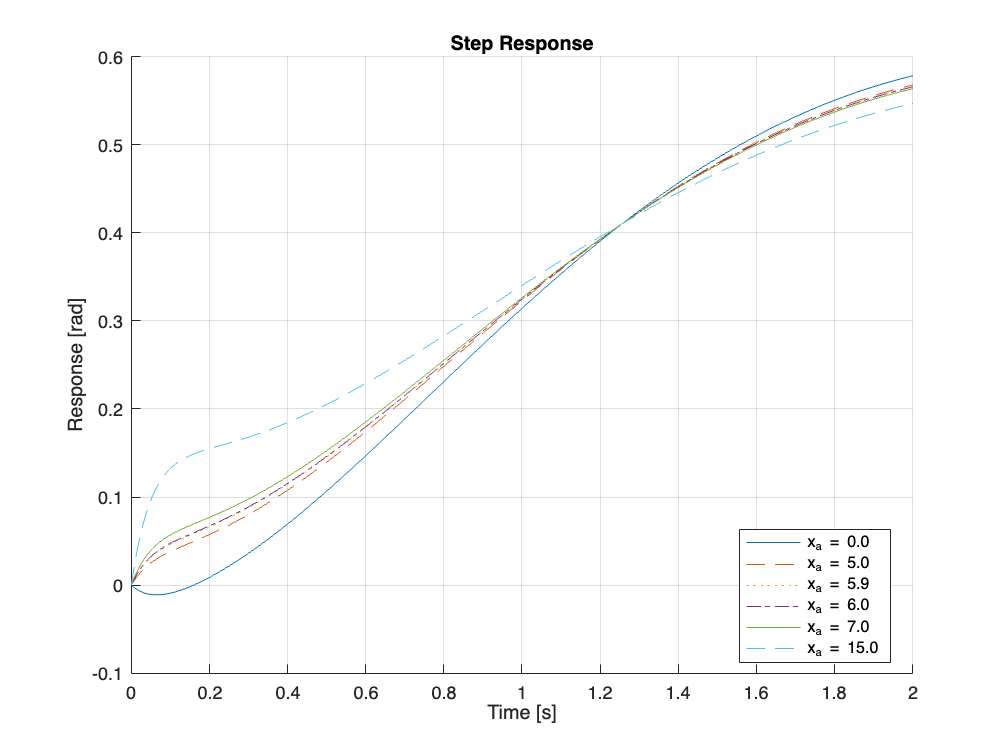


% Limit the y-axis to 0.08
%ylim([0, 0.08]);

% Limit the x-axis to 0.3
xlim([0, 2]);
%xlim([0, 10]);
% Label the axes
xlabel('Time [s]');
ylabel('Response [rad]');

% Add a title
title('Step Response');

% Add a legend to identify each line
legend('Location', 'Best');

% Add a grid for better readability
grid on;